正弦函数分布 SSPH插值

初始化参数

clear;
clc;
close all;

L = 1;   % computational domain
dx = 0.001;
N = L/dx + 1; %space step
x = 0:dx:L;  % space grid
v = 1; %velocity（constant）

M = 100;
Cr = 0.6;
dt = Cr*dx/v;
T = (M-1) * dt;
t = 0:dt:T;

P = 5000;
D = v*L/P

D = 2.0000e-04

m = 1;

初始化浓度分布


%% 初始浓度为正弦分布
omega = 5;  %sigma


u=zeros(M,N);
ux=zeros(M,N);  % derivative浓度空间一阶导
exact_u=zeros(M,N);  %exact solution精确解


%% 初始状态浓度分布
u(1,:) = sin(2*omega*pi*x);
%% 初始导数
ux(1,:) = 2*omega*pi*cos(2*omega*pi*x);

%% add diffusion process（加上扩散过程） 
r = (dt*D)/(dx^2 * 2);   %constant speed
 
tic 
for n=2:M
    u_temp = zeros(1,N);
    pp = spline(x, u(n-1,:));
    for i=2:N-1 
        parcenter = [(i-1)*dx-dt*v, 0];
        u(n,i) = ppval(pp, parcenter(1));
    end
    u(n,1)=sin(-2*omega*pi*t(n))*exp(-4*pi^2*omega^2*t(n)/P);
    u(n,N)=sin(2*omega*pi*(1-t(n)))*exp(-4*pi^2*omega^2*t(n)/P);
    for i=2:N-1  
%         u_temp(i) = u(n,i) + r*(u(n-1,i+1) - 2*u(n-1,i) + u(n-1,i-1));
%         ux_temp(i) = ux(n,i) + r*(ux(n-1,i+1) - 2*ux(n-1,i) + ux(n-1,i-1));
        u_temp(i) = u(n,i) + r*(u(n,i+1) - 2*u(n,i) + u(n,i-1));
    end
    u_temp(1)=sin(-2*omega*pi*t(n))*exp(-4*pi^2*omega^2*t(n)/P);
    u_temp(N)=sin(2*omega*pi*(1-t(n)))*exp(-4*pi^2*omega^2*t(n)/P);
    u(n,:) = u_temp;

% 纯对流
    u(n,1)=sin(-2*omega*pi*t(n))*exp(-4*pi^2*omega^2*t(n)/P);
    u(n,N)=sin(2*omega*pi*(1-t(n)))*exp(-4*pi^2*omega^2*t(n)/P);
end
toc

历时 0.890732 秒。


精确解

for n = 1:M
    exact_u(n,:)=sin(2*omega*pi*(x-t(n)))*exp(-4*pi^2*omega^2*t(n)/P);
end

% 纯对流
% for n = 1:M
%     exact_u(n,:)=sin(2*omega*pi*(x-t(n)));
% end

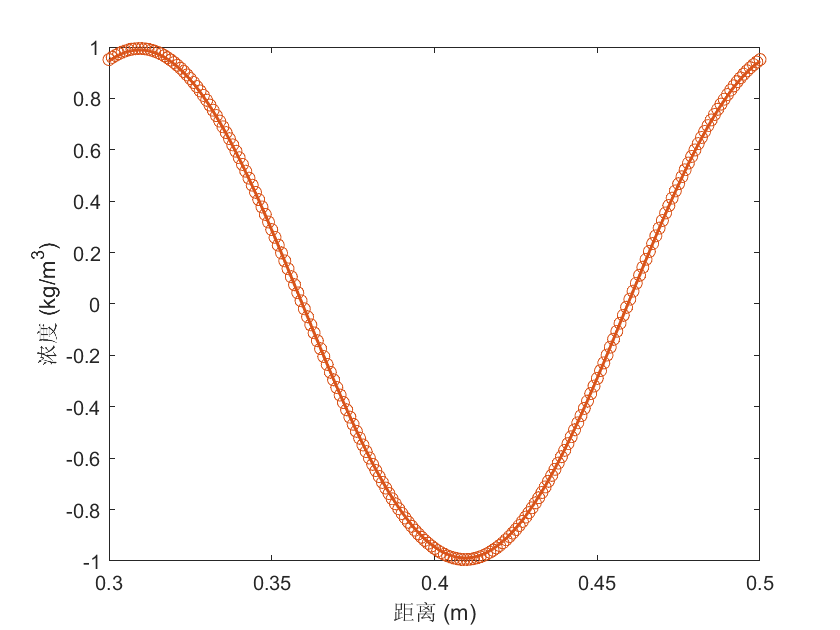


hold on
box on
lt = T;
color=[[0.85, 0.33, 0.10],[0.93, 0.69, 0.13],[0.00, 0.45, 0.74],[0.49,0.18,0.56]];
style = {'o', 's', 'd'};
for i=1:length(lt) 
    plot(x(1:N),u(round(lt(i)/dt)+1,1:N),'LineStyle','none','Marker',char(style(i)),'Color',color(3*i-2:3*i),"LineWidth",0.1)
    plot(x(1:N),exact_u(round(lt(i)/dt)+1,1:N),'Color',color(3*i-2:3*i),"LineWidth",1.3)
end
xlabel('距离 (m)')
ylabel('浓度 (kg/m^3)');
xlim([0.3 0.5]);


%% error analysis
up = 0;
down = 0;

for i= 1:N
    up = up+abs(u(M,i)-exact_u(M,i));
    down = down +abs(exact_u(M,i));
end
Re=up/down*100;
disp(strcat('相对误差',num2str(Re)));

相对误差0.56283


log10(Re)

ans = -0.2496

log10(dx)

ans = -3



%% 结论
% dx = 0.025 Cr<1时，Cr越接近1效果越好

rmse = sqrt(mean((u(M,:) - exact_u(M,:)).^2))

rmse = 0.0040